# Global fit of a time-domain parameteric 4-pulse DEER dipolar signal 

#### Author: Luis Fabregas

In this tutorial we will expand the concepts introduced in another tutorial (*Fitting a custom time-domain model of a 4-pulse DEER signal*) to the global fit of multiple datasets. 

## Generating multiple datasets

In this example we will consider the following situation: given a set of samples with the same bimodal distance distribution, we performed measurements on each of them of varying length and with different number of shots (hence different noise levels). For this situation to be valid it is also important that the relaxation effects are neglibible. Otherwise the assumption that the distance distribution is the same for all measurements would not be valid.

First, let's generate the three dipolar signals `V1`,`V2` and `V3` of different background, length, and noise levels. All of them arising from the same bimodal distance distribution. We assume the modulation depths to be approximately equal between measurements.

clear,clc,clf

%Model input parameters
k = 0.3;
lam = 0.35;
rmean1 = 3;
rmean2 = 3.5;
w1 = 0.3;
w2 = 0.3;
A1 = 0.3;

%Construct the axes
t1 = linspace(0,5,200);
t2 = linspace(0,2,100);
t3 = linspace(0,3,150);
r = linspace(2,5,100);

%Generate components
P = rd_twogaussian(r,[rmean1 w1 rmean2 w2 A1]);
B1 = td_exp(t1,k);
B2 = td_exp(t2,k);
B3 = td_exp(t3,k);

%Generate dipolar signals
V1 = dipolarsignal(t1,r,P,'Background',B1,'noiselevel',0.10,'moddepth',lam);
V2 = dipolarsignal(t2,r,P,'Background',B2,'noiselevel',0.02,'moddepth',lam);
V3 = dipolarsignal(t3,r,P,'Background',B3,'noiselevel',0.05,'moddepth',lam);

## Global fit

Doing this global fit does not require any additional steps in comparison to the local fits. 

First we construct our time-domain parameteric model using the exponential background model and the two-Gaussian distance-domain model.

% Construct time-domain model function including background
mymodel = @(t,p) td_exp(t,p(2)).*((1- p(1)) + p(1)*dipolarkernel(t,r)*rd_twogaussian(r,p(3:end)));

Next we define the lower and upper bounds of the model parameters as well as their inital values.

% Define lower/upper bounds and initial guess of parameters
upper = [1 200 20 5 20 5 1];
lower = [0 0 1.0 0.2 1.0 0.2 0];
param0 = [0.5 0.5 2 0.2 3.5 0.4 0.4];

Finally in order to perform the fit in a global way, we only need to pass all signals as a cell array `{V1,V2,V3}`. Since we are dealing with a time-domain model we also need to pass the different time-axis vectors as a cell-array `{t1,t2,t3}`.

%Run global fit of time-domain parameteric model
[param,Vfit] = fitparamodel({V1,V2,V3},mymodel,{t1,t2,t3},param0,'Upper',upper,'Lower',lower);
%Get the globally fitted distance distribution
Pfit = rd_twogaussian(r,param(3:end));

For the sake of comparison, we will also compute the locally fitted distance distributions of the individual dipolar signals.

%Fit the individual traces for comparison
[param1,Vfit1] = fitparamodel(V1,mymodel,t1,param0,'Upper',upper,'Lower',lower);
[param2,Vfit2] = fitparamodel(V2,mymodel,t2,param0,'Upper',upper,'Lower',lower);
[param3,Vfit3] = fitparamodel(V3,mymodel,t3,param0,'Upper',upper,'Lower',lower);

%Get the locally fitted distance distributions
Pfit1 = rd_twogaussian(r,param1(3:end));
Pfit2 = rd_twogaussian(r,param2(3:end));
Pfit3 = rd_twogaussian(r,param3(3:end));

Finally we can plot all our results and compare them to the ground truth.

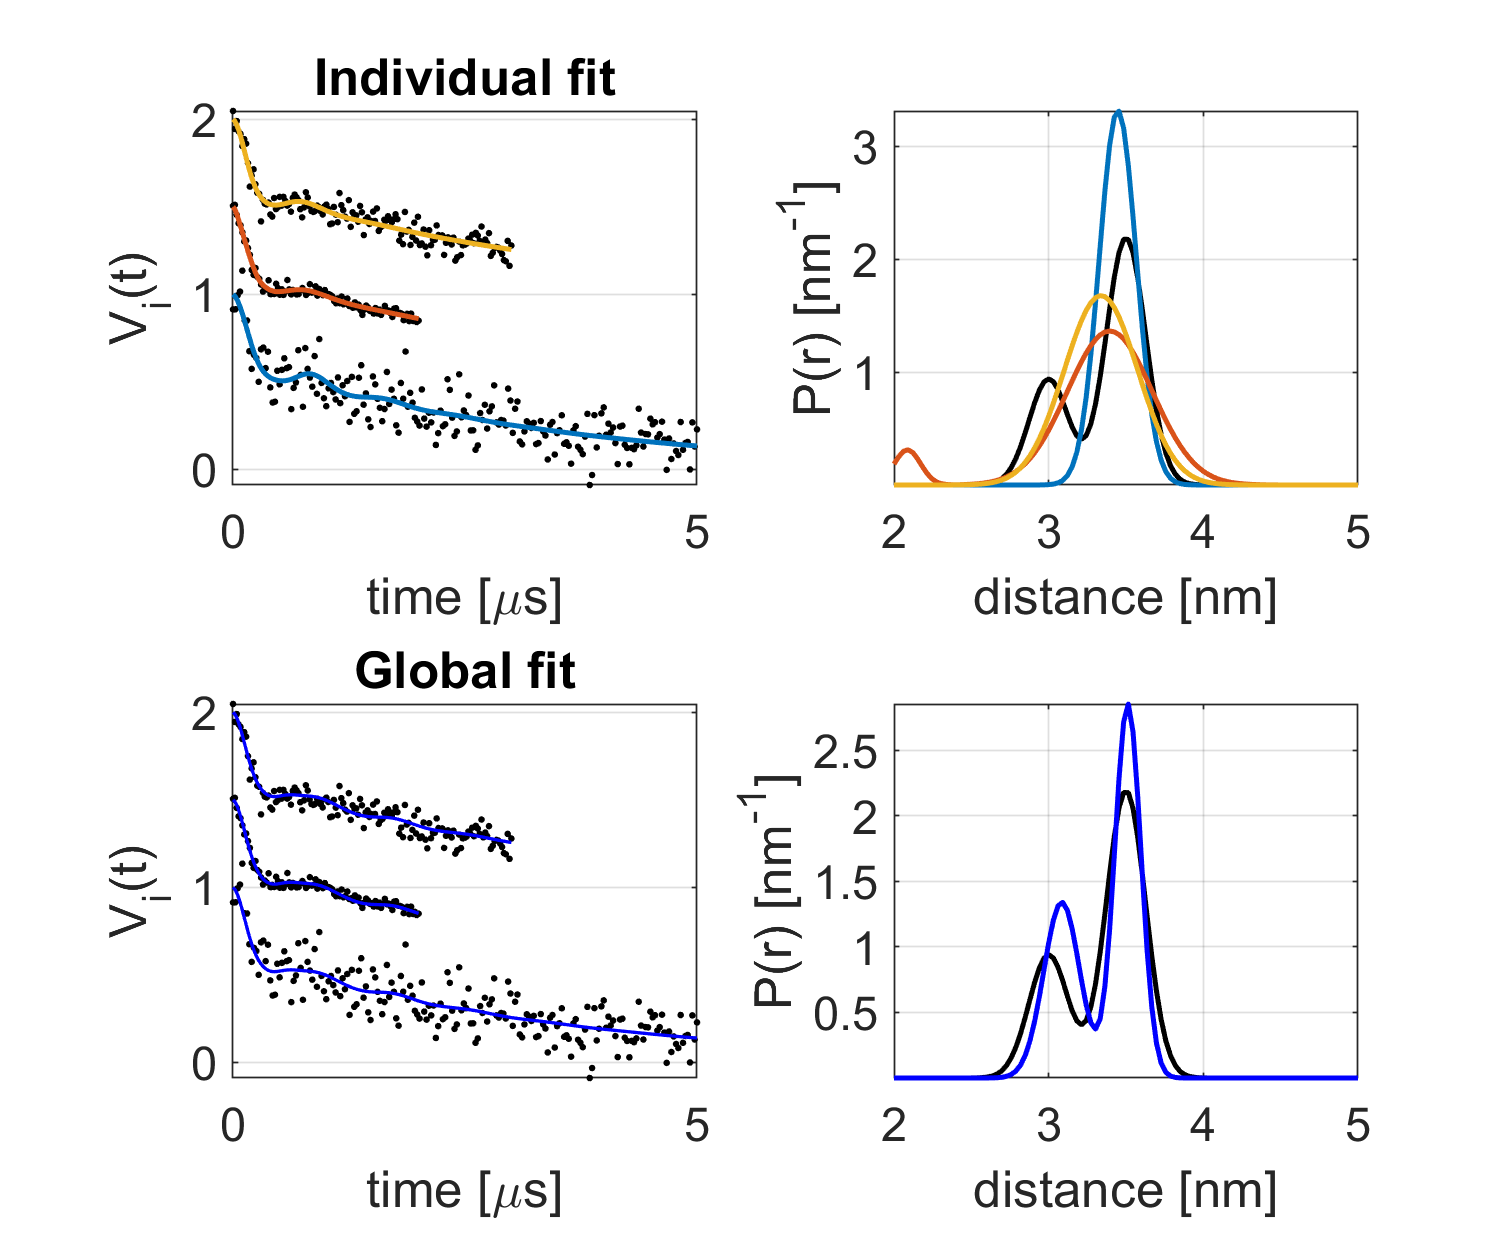

%Plotting
figure('position',[0 0 600 500]),clf

subplot(221)
plot(t1,V1,'k.',t1,Vfit1,t2,V2+1/2,'k.',t2,Vfit2+1/2,t3,V3+1,'k.',t3,Vfit3+1,'LineWidth',1.5)
grid on,axis tight,box on
xlabel('time [\mus]')
ylabel('V_i(t)')
set(gca,'FontSize',14)
title('Individual fit')

subplot(222)
plot(r,P,'k',r,Pfit1,r,Pfit2,r,Pfit3,'LineWidth',1.5)
grid on,axis tight,box on
xlabel('distance [nm]')
set(gca,'FontSize',14)
ylabel('P(r) [nm^{-1}]')

subplot(223)
plot(t1,V1,'k.',t1,Vfit{1},'b',t2,V2+1/2,'k.',t2,Vfit{2}+1/2,'b',t3,V3+1,'k.',t3,Vfit{3}+1,'b','LineWidth',1)
grid on,axis tight,box on
xlabel('time [\mus]')
ylabel('V_i(t)')
set(gca,'FontSize',14)
title('Global fit')

subplot(224)
plot(r,P,'k',r,Pfit,'b','LineWidth',1.5)
grid on,axis tight,box on
xlabel('distance [nm]')
ylabel('P(r) [nm^{-1}]')
set(gca,'FontSize',14)